# PubChem_SDQ_LitSearch

Search PubChem for PubMed, Patent, Springer Nature, Thieme, and Wiley Literature associated with a CID

% Vincent F. Scalfani, Serena C. Ralph, Ali Al Alshaikh, and Jason E. Bara 
% The University of Alabama
% Tested with MATLAB R2020a, running Ubuntu 18.04 on March 30, 2020.
% N.B. PubChem SDQ is used internally by PubChem webpages and is still being rapidly developed.

## Define the PubChem API and SDQ agent base URL

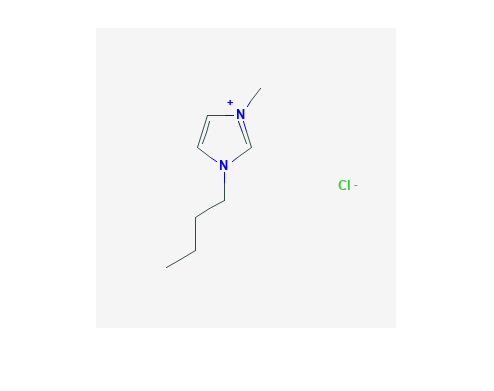

% PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/cid/';

% PubChem SDQ agent
sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';

% set a longer web options timeout and json output
options = weboptions('Timeout', 60, 'ContentType','json');

% Retrieve and display PNG Image of 1-Butyl-3-methylimidazolium chloride;
% CID 2734161
CID_query = '2734161';
CID_query_url = [api CID_query '/PNG'];
[CID_img,map] = imread(CID_query_url);
imshow(CID_img,map);

*Replace the above CID value (CID) with a different CID number to customize*

## Explore Total Literature and Data Counts

% Retrieve total count of associated literature references
litCountQ_url = [sdq '{"hide":"*","collection":"*","where":{"ands":{"cid":"' CID_query '"}}}'];
litCountQ = webread(litCountQ_url, options);

% display all available collections
collections = cell(1,length(litCountQ.SDQOutputSet)); % preallocate
for k = 1:length(litCountQ.SDQOutputSet)
    collections{k} = litCountQ.SDQOutputSet{k, 1}.collection;
end
collections = collections'

collections = 33×1 cell array
    {'compound'         }
    {'substance'        }
    {'assay'            }
    {'patent'           }
    {'pathway'          }
    {'disease'          }
    {'pubmed'           }
    {'targetprotein'    }
    {'targetgene'       }
    {'targettaxonomy'   }
    {'classification'   }
    {'literature'       }
    {'thiemechemistry'  }
    {'wiley'            }
    {'springernature'   }
    {'hmdb'             }
    {'epapest'          }
    {'clinicaltrials'   }
    {'drugbank'         }
    {'gtopdb'           }
    {'geneinteractions' }
    {'probereports'     }
    {'niosh'            }
    {'chembldrugtargets'}
    {'dgidb'            }
    {'pdb'              }
    {'fdaorangebook'    }
    {'chemidplus'       }
    {'clinicaltrials_eu'}
    {'clinicaltrials_jp'}


% Display total literature counts of selected collections:
% pubmed, patent, springernature, thiemechemistry, and wiley

litCountQ_pubmed = litCountQ.SDQOutputSet{7,1}.totalCount;
litCountQ_patent = litCountQ.SDQOutputSet{4,1}.totalCount;
litCountQ_springernature = litCountQ.SDQOutputSet{15,1}.totalCount;
litCountQ_thieme = litCountQ.SDQOutputSet{13,1}.totalCount;
litCountQ_wiley = litCountQ.SDQOutputSet{14,1}.totalCount;

fprintf(['litCountQ_pubmed = %d \nlitCountQ_patent = %d \nlitCountQ_springernature = %d' ...
    '\nlitCountQ_thieme = %d \nlitCountQ_wiley = %d'] ,...
    litCountQ_pubmed, litCountQ_patent, litCountQ_springernature, litCountQ_thieme, litCountQ_wiley)

litCountQ_pubmed = 323 
litCountQ_patent = 772 
litCountQ_springernature = 1182
litCountQ_thieme = 2 
litCountQ_wiley = 9

*If interested in different collections:*

- *Determine the collection you are interested in (e.g., 'clinicaltrials') from the litCountQ.SDQOutputSet structure*

- *Then, record the row number the collection appears in (18 for 'clinicaltrials')*

- *Next, use this number to index into the litCountQ.SDQOutputSet *

- *For example, litCountQ.SDQOutputSet{18,1}.totalCount*

## Explore Categories of the Literature Data

% Retrieve 1 associated literature reference from each selected collection to look at 
% JSON field data

% pubmed
litQpubmed1_url = [sdq '{"select":"*","collection":"pubmed","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":1}'];
litQpubmed1 = webread(litQpubmed1_url, options);
disp(litQpubmed1.SDQOutputSet.rows)

               pmid: 15770258
               cids: '5793,2734161,2734236,10265934,12095228,16211032,24802025'
               sids: '128353538,129621433'
     articlepubdate: '20050328'
       articletitle: 'High-resolution 13C NMR studies of cellulose and cellulose oligomers in ionic liquid solutions.'
    articleabstract: 'High-resolution 13C NMR studies of cellulose and cellulose oligomers dissolved in the ionic liquid (IL) 1-butyl-3-methylimidazolium chloride ([C4mim]Cl) show that the beta-(1-->4)-linked glucose oligomers are disordered in this medium and have a conformational behavior which parallels the one observed in water, and thus, reveal that the polymer is disordered in IL solution as well. '
    articlejourname: 'Chemical communications (Cambridge, England)'
        articleauth: 'Jason S Moulthrop, Richard P Swatloski, Guillermo Moyna, Robin D Rogers'
       articleaffil: 'Department of Chemistry & Biochemistry, University of the Sciences in Philadelphia, 600 South 43rd Str

% patent
litQpatent1_url = [sdq '{"select":"*","collection":"patent","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":1}'];
litQpatent1 = webread(litQpatent1_url, options);
disp(litQpatent1.SDQOutputSet.rows)

                scoreint: 1610592
                     pid: 2794311
                    cids: '335,342,874,6623,6917,6998,7107,7108,7877,8154,8155,10413,13360,14471,15371,17111,17238,17583,17587,17869,24756,25945,33286,33287,62474,62696,65360,66666,68114,70218,74406,77452,77495,78875,83191,90558,93085,95149,122390,137811,139428,168725,169580,170750,172281,444539,523077,643460,2734160,2734161,6327420,9793705,10313247,11045164,11105370,11160059,11160060,11492381,11579446,12562731,13016669,15752066,16211088,16211849,16760658,18352041,18691638,21881833,22056982,22056987,22056988,22056995,22056997,2205701'
                    sids: '127391821,127766595,128020427,128084881,128288294,128583861,128666970,128711444,128721138,128758049,128809562,128829724,128853801,128866908,128936893,129126799,129165249,129258501,129299320,129372462,129566447,129573643,129589511,129680599,129691562,129747353,129749502,129800949,129812001,129828571,129942363,129954420,226394094,226394314,226394442,226396296,2263

% springernature
litQspringernature1_url = [sdq '{"select":"*","collection":"springernature","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":1}'];
litQspringernature1 = webread(litQspringernature1_url, options);
disp(litQspringernature1.SDQOutputSet.rows)

                cid: 2734161
                sid: 341356859
                oid: 1580860
               pmid: 21107800
         openaccess: 0
         scorefloat: 1.3502
     articlepubdate: '2008'
       articletitle: 'NMR Spectroscopy in Ionic Liquds'
    articlejourname: 'Ionic Liquids'
            subject: 'Chemistry and Material Science'
            doctype: 'book chapter'
           language: 'En'
                doi: '10.1007/128_2008_37'
                url: 'https://doi.org/10.1007/128_2008_37'
           imageurl: 'https://pubchem.ncbi.nlm.nih.gov/image/imgsrv.fcgi?doi=10.1007/128_2008_37'
              extid: '11043100-707487210'



% thiemechemistry
litQthieme1_url = [sdq '{"select":"*","collection":"thiemechemistry","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":1}'];
litQthieme1 = webread(litQthieme1_url, options);
disp(litQthieme1.SDQOutputSet.rows)

                cid: 2734161
                sid: 376961291
                oid: 101527
         openaccess: 0
     articlepubdate: '2014'
       articletitle: 'Synthesis from Alkanesulfonates'
    articlejourname: 'Science of Synthesis'
           citation: 'Margaretha, P., Science of Synthesis Knowledge Updates, (2014) 2, 426.'
            doctype: 'book chapter'
           language: 'En'
                url: 'https://science-of-synthesis.thieme.com/app/text/?id=SD-135-00011'
              extid: '11043100-707488334'



% wiley
litQpwiley1_url = [sdq '{"select":"*","collection":"wiley","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":1}'];
litQwiley1 = webread(litQpwiley1_url, options);
disp(litQwiley1.SDQOutputSet.rows)

                cid: 2734161
                sid: 386221839
                oid: 138912
     articlepubdate: '2014'
       articletitle: 'LiBF4 integrated into [BMIm]BF4: an ionic-liquid metal composite and homogeneous catalyst for efficient synthesis of pyran-annulated heterocycles'
    articlejourname: 'Applied Organometallic Chemistry'
                doi: '10.1002/aoc.3099'
                url: 'https://doi.org/10.1002/aoc.3099'
              extid: '31910'



*In each collection there are multiple unique searchable fields that we can use to perform literature searching. Some examples are presented below for how to combine the fields with keywords. Please note that this is still an experimental method. The limit was set at 10 for demo purposes.*

## Search PubMed Collection

% Search pubchem pubmed collection for 
% referencess containing meshheadings "Imidazoles" and meshsubheadings "chemical synthesis"
% (associated with CID_query)

litQpubmedF = [sdq '{"select":"*","collection":"pubmed","where":{"ands":{"cid":"' CID_query '",' ...
    '"meshheadings":"Imidazoles", "meshsubheadings":"chemical synthesis"}},"start":1,"limit":10}'];
options = weboptions('Timeout', 60, 'ContentType','json');
litQpubmedF = webread(litQpubmedF, options);

% Display results: pmid, articletitle, articlejourname, articleauth, pubmed link
for k = 1:length(litQpubmedF.SDQOutputSet.rows)
    pmid = litQpubmedF.SDQOutputSet.rows{k,1}.pmid
    articletitle = litQpubmedF.SDQOutputSet.rows{k,1}.articletitle
    articleauth = litQpubmedF.SDQOutputSet.rows{k,1}.articleauth
    articlejourname = litQpubmedF.SDQOutputSet.rows{k,1}.articlejourname
    citation = litQpubmedF.SDQOutputSet.rows{k,1}.citation
    
    pubmed_root = 'https://www.ncbi.nlm.nih.gov/pubmed/?term=';
    pmid = num2str(pmid);
    pubmed_link = [pubmed_root pmid];
    fprintf('<a href = " %s ">%s</a>\n', pubmed_link, pubmed_link)
    disp(' ')
end

pmid = 24307868

articletitle = 'Synthesis, characterization and application of 1-butyl-3 methylimidazolium chloride as green material for extractive desulfurization of liquid fuel.'

articleauth = 'Swapnil A Dharaskar, Mahesh N Varma, Diwakar Z Shende, Chang Kyoo Yoo, Kailas L Wasewar'

articlejourname = 'TheScientificWorldJournal'

citation = '2013 ; 2013(?):395274'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=24307868 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=24307868</a>


pmid = 20582335

articletitle = 'Ultrathin SmVO4 nanosheets: ionic liquid-assisted hydrothermal synthesis, characterization, formation mechanism and optical property.'

articleauth = 'Yan Sun, Wenjun Zheng'

articlejourname = 'Dalton transactions (Cambridge, England : 2003)'

citation = '2010 Aug; 39(30):7098-7103'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=20582335 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=20582335</a>


pmid = 30760673

articletitle = 'One Step Conversion of Glucose into 5-Hydroxymethylfurfural (HMF) via a Basic Catalyst in Mixed Solvent Systems of Ionic Liquid-Dimethyl Sulfoxide.'

articleauth = 'Zhe Tang, Jianhui Su'

articlejourname = 'Journal of oleo science'

citation = '2019 Mar; 68(3):261-271'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=30760673 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=30760673</a>


pmid = 31121813

articletitle = 'Domino Multicomponent Approach for the Synthesis of Functionalized Spiro-Indeno[1,2-b]quinoxaline Heterocyclic Hybrids and Their Antimicrobial Activity, Synergistic Effect and Molecular Docking Simulation.'

articleauth = 'Abdulrahman I Almansour, Natarajan Arumugam, Raju Suresh Kumar, Dhaifallah M Al-Thamili, Govindasami Periyasami, Karuppiah Ponmurugan, Naif Abdullah Al-Dhabi, Karthikeyan Perumal, Dhanaraj Premnath'

articlejourname = 'Molecules (Basel, Switzerland)'

citation = '2019 May; 24(10):'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=31121813 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=31121813</a>


pmid = 16917949

articletitle = 'Enhancement of cellulose saccharification kinetics using an ionic liquid pretreatment step.'

articleauth = 'Anantharam P Dadi, Sasidhar Varanasi, Constance A Schall'

articlejourname = 'Biotechnology and bioengineering'

citation = '2006 Dec; 95(5):904-910'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=16917949 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=16917949</a>


pmid = 19384978

articletitle = 'Application of 1-allyl-3-(1-butyl)imidazolium chloride in the synthesis of cellulose esters: properties of the ionic liquid, and comparison with other solvents.'

articleauth = 'Ludmila C Fidale, Shirley Possidonio, Omar A El Seoud'

articlejourname = 'Macromolecular bioscience'

citation = '2009 Aug; 9(8):813-821'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=19384978 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=19384978</a>


pmid = 21742316

articletitle = 'Synthesis of cellulose dehydroabietate in ionic liquid [bmim]Br'

articleauth = 'Xuetang Xu, Wengui Duan, Mei Huang, Guanghua Li'

articlejourname = 'Carbohydrate research'

citation = '2011 Sep; 346(13):2024-2027'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=21742316 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=21742316</a>


pmid = 21809450

articletitle = 'A study of the acid-catalyzed hydrolysis of cellulose dissolved in ionic liquids and the factors influencing the dehydration of glucose and the formation of humins.'

articleauth = 'Sean J Dee, Alexis T Bell'

articlejourname = 'ChemSusChem'

citation = '2011 Aug; 4(8):1166-1173'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=21809450 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=21809450</a>


pmid = 21989309

articletitle = 'An unexpected reaction between 5-hydroxymethylfurfural and imidazolium-based ionic liquids at high temperatures.'

articleauth = 'Zehui Zhang, Wujun Liu, Haibo Xie, Zongbao K Zhao'

articlejourname = 'Molecules (Basel, Switzerland)'

citation = '2011 Oct; 16(10):8463-8474'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=21989309 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=21989309</a>


pmid = 23694706

articletitle = 'Microwave-assisted rapid conversion of carbohydrates into 5-hydroxymethylfurfural by ScCl3 in ionic liquids.'

articleauth = 'Xuanmu Zhou, Zehui Zhang, Bing Liu, Zheng Xu, Kejian Deng'

articlejourname = 'Carbohydrate research'

citation = '2013 Jun; 375(?):68-72'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=23694706 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=23694706</a>


## Search Patent Collection

% Search pubchem patent collection for patents with "imidazolium" in the abstract and "preparation" in the title
% (associated with CID_query)
litQpatentF = [sdq '{"select":"*","collection":"patent","where":{"ands":{"cid":"' CID_query '",' ...
    '"patentabstract":"imidazolium", "patenttitle":"preparation"}},"start":1,"limit":10}'];
options = weboptions('Timeout', 60, 'ContentType','json');
litQpatentF = webread(litQpatentF, options);

% Display results: patentID, patenttitle, patentinventor, and patenturl
for k = 1:length(litQpatentF.SDQOutputSet.rows)
    patentID = litQpatentF.SDQOutputSet.rows{k,1}.patentid
    patenttitle = litQpatentF.SDQOutputSet.rows{k,1}.patenttitle
    patentdate = litQpatentF.SDQOutputSet.rows{k,1}.patentdate
    patentinventor = litQpatentF.SDQOutputSet.rows{k,1}.patentinventor
    patenturl = litQpatentF.SDQOutputSet.rows{k,1}.patenturl;
    fprintf('<a href = " %s ">%s</a>', patenturl, patenturl)
    disp(' ')
end

patentID = 'US8821716'

patenttitle = 'Desulfurization of hydrocarbons by ionic liquids and preparation of ionic liquids'

patentdate = '20091126'

patentinventor = 'MARTINEZ PALOU RAFAEL [MX],PALOMEQUE SANTIAGO JORGE FROYLAN [MX],VICTOROVNA LIKHANOVA NATALYA [MX]'

<a href = " http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20090288992.PN.&OS=PN/20090288992&RS=PN/20090288992 ">http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20090288992.PN.&OS=PN/20090288992&RS=PN/20090288992</a>

patentID = 'US2013118955'

patenttitle = 'DESULFURIZATION OF HYDROCARBONS BY IONIC LIQUIDS AND PREPARATION OF IONIC LIQUIDS'

patentdate = '20130516'

patentinventor = 'Jorge Froylan PALOMEQUE SANTIAGO,Natalya VICTOROVNA LIKHANOVA,Rafael MARTINEZ PALOU'

<a href = " http://appft1.uspto.gov/netacgi/nph-Parser?Sect1=PTO1&Sect2=HITOFF&d=PG01&p=1&u=/netahtml/PTO/srchnum.html&r=1&f=G&l=50&s1=20130118955.PGNR.&OS=DN/20130118955&RS=DN/20130118955 ">http://appft1.uspto.gov/netacgi/nph-Parser?Sect1=PTO1&Sect2=HITOFF&d=PG01&p=1&u=/netahtml/PTO/srchnum.html&r=1&f=G&l=50&s1=20130118955.PGNR.&OS=DN/20130118955&RS=DN/20130118955</a>

patentID = 'US2018142058'

patenttitle = 'A Curing Agent For Thermosetting Epoxy Resins, and a Process for the Preparation of Insulation Systems for Electrical Engineering'

patentdate = '20160511'

patentinventor = 'Catherine Schoenenberger,Christian Beisele,Sophie Colliard'

<a href = " http://appft1.uspto.gov/netacgi/nph-Parser?Sect1=PTO1&Sect2=HITOFF&d=PG01&p=1&u=/netahtml/PTO/srchnum.html&r=1&f=G&l=50&s1=20180142058.PGNR.&OS=DN/20180142058&RS=DN/20180142058 ">http://appft1.uspto.gov/netacgi/nph-Parser?Sect1=PTO1&Sect2=HITOFF&d=PG01&p=1&u=/netahtml/PTO/srchnum.html&r=1&f=G&l=50&s1=20180142058.PGNR.&OS=DN/20180142058&RS=DN/20180142058</a>

patentID = 'US7825259'

patenttitle = 'Method of preparation of halogen-free ionic liquids and ionic liquids prepared in this manner'

patentdate = '20101102'

patentinventor = 'CASSOL CLAUDIA CRISTIANA [BR],DUPONT JAIRTON [BR],EBELING GUNTER [BR],FERRERA BAUER COSTA [BR]'

<a href = " http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=7825259.PN.&OS=PN/7825259&RS=PN/7825259 ">http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=7825259.PN.&OS=PN/7825259&RS=PN/7825259</a>

## Search Springer Nature

% Search springer nature collection for "imidazolium" in the title and publication year 2019
% (associated with CID_query)
litQspringernatureF = [sdq '{"select":"*","collection":"springernature","where":{"ands":{"cid":"' CID_query '",' ...
    '"articletitle":"imidazolium", "articlepubdate":"2019"}},"start":1,"limit":10}'];
options = weboptions('Timeout', 60, 'ContentType','json');
litQspringernatureF = webread(litQspringernatureF, options);

% Display results
for k = 1:length(litQspringernatureF.SDQOutputSet.rows)
    extID = litQspringernatureF.SDQOutputSet.rows{k,1}.extid
    articletitle = litQspringernatureF.SDQOutputSet.rows{k,1}.articletitle
    articlejournalname = litQspringernatureF.SDQOutputSet.rows{k,1}.articlejourname
    articlepubdate = litQspringernatureF.SDQOutputSet.rows{k,1}.articlepubdate
    articleurl = litQspringernatureF.SDQOutputSet.rows{k,1}.url;
    fprintf('<a href = " %s ">%s</a>', articleurl, articleurl)
    disp(' ')
end

extID = '11043100-876939421'

articletitle = 'Insights into the effect of imidazolium-based ionic liquids on chemical structure and hydrolytic activity of microbial lipase'

articlejournalname = 'Bioprocess and Biosystems Engineering'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s00449-019-02121-w ">https://doi.org/10.1007/s00449-019-02121-w</a>

extID = '11043100-876939421'

articletitle = 'As Catalytic as Silver Nanoparticles Anchored to Reduced Graphene Oxide: Fascinating Activity of Imidazolium Based Surface Active Ionic Liquid for Chemical Degradation of Rhodamine B'

articlejournalname = 'Catalysis Letters'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s10562-019-02798-4 ">https://doi.org/10.1007/s10562-019-02798-4</a>

extID = '11043100-876939421'

articletitle = 'Imidazolium-based ionic liquid surfactants as pseudostationary in combination with a chiral selector in micellar electrokinetic chromatography'

articlejournalname = 'Analytical and Bioanalytical Chemistry'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s00216-019-01861-8 ">https://doi.org/10.1007/s00216-019-01861-8</a>

extID = '11043100-707487210'

articletitle = 'Scaling analysis on the linear viscoelasticity of cellulose 1-ethyl-3-methyl imidazolium acetate solutions'

articlejournalname = 'Korea-Australia Rheology Journal'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s13367-019-0014-5 ">https://doi.org/10.1007/s13367-019-0014-5</a>

extID = '11043100-707487210'

articletitle = 'Microwave-Assisted Lignin Solubilization in Protic Ionic Compounds Containing 2,3,4,5-Tetraphenyl-1H-imidazolium and Inorganic Anions'

articlejournalname = 'Waste and Biomass Valorization'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s12649-019-00916-2 ">https://doi.org/10.1007/s12649-019-00916-2</a>

## Retrieve Thieme and Wiley Chemistry References

% Retrieve all Thieme and Wiley Chemistry References associated with our
% CID query (since both are < 10 results)
% (associated with CID_query)

% Thieme
litQthiemeF = [sdq '{"select":"*","collection":"thiemechemistry","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":10}'];

options = weboptions('Timeout', 60, 'ContentType','json');
litQthiemeF = webread(litQthiemeF, options);

% Display results
for k = 1:length(litQthiemeF.SDQOutputSet.rows)
    extID = litQthiemeF.SDQOutputSet.rows(k).extid
    articletitle = litQthiemeF.SDQOutputSet.rows(k).articletitle
    articlejournalname = litQthiemeF.SDQOutputSet.rows(k).articlejourname
    articlepubdate = litQthiemeF.SDQOutputSet.rows(k).articlepubdate
    articleurl = litQthiemeF.SDQOutputSet.rows(k).url;
    fprintf('<a href = " %s ">%s</a>', articleurl, articleurl)
    disp(' ')
end

extID = '11043100-707488334'

articletitle = 'Synthesis from Alkanesulfonates'

articlejournalname = 'Science of Synthesis'

articlepubdate = '2014'

<a href = " https://science-of-synthesis.thieme.com/app/text/?id=SD-135-00011 ">https://science-of-synthesis.thieme.com/app/text/?id=SD-135-00011</a>

extID = '11043100-876940370'

articletitle = 'Aluminum Halides with Onium Salts'

articlejournalname = 'Science of Synthesis'

articlepubdate = '2010'

<a href = " https://science-of-synthesis.thieme.com/app/text/?id=SD-107-00240 ">https://science-of-synthesis.thieme.com/app/text/?id=SD-107-00240</a>

% Wiley
litQwileyF = [sdq '{"select":"*","collection":"wiley","where":{"ands":{"cid":"' CID_query '"}},' ...
    '"start":1,"limit":10}'];

options = weboptions('Timeout', 60, 'ContentType','json');
litQwileyF = webread(litQwileyF, options);

% Display results
for k = 1:length(litQwileyF.SDQOutputSet.rows)
    extID = litQwileyF.SDQOutputSet.rows(k).extid
    articletitle = litQwileyF.SDQOutputSet.rows(k).articletitle
    articlejournalname = litQwileyF.SDQOutputSet.rows(k).articlejourname
    articlepubdate = litQwileyF.SDQOutputSet.rows(k).articlepubdate
    articleurl = litQwileyF.SDQOutputSet.rows(k).url;
    fprintf('<a href = " %s ">%s</a>', articleurl, articleurl)
    disp(' ')
end

extID = '31910'

articletitle = 'LiBF4 integrated into [BMIm]BF4: an ionic-liquid metal composite and homogeneous catalyst for efficient synthesis of pyran-annulated heterocycles'

articlejournalname = 'Applied Organometallic Chemistry'

articlepubdate = '2014'

<a href = " https://doi.org/10.1002/aoc.3099 ">https://doi.org/10.1002/aoc.3099</a>

extID = '31910'

articletitle = 'Controlled ring-opening polymerization of trimethylene carbonate and access to PTMC-PLA block copolymers mediated by well-defined N-heterocyclic carbene zinc alkoxides'

articlejournalname = 'Applied Organometallic Chemistry'

articlepubdate = '2014'

<a href = " https://doi.org/10.1002/aoc.3154 ">https://doi.org/10.1002/aoc.3154</a>

extID = '31910'

articletitle = 'Ionic Liquid-Mediated Facile Synthesis of Novel Spiroheterobicyclic Rings as Potential Antifungal and Antibacterial Drugs'

articlejournalname = 'J. Heterocyclic Chem.'

articlepubdate = '2013'

<a href = " https://doi.org/10.1002/jhet.1002 ">https://doi.org/10.1002/jhet.1002</a>

extID = '31910'

articletitle = '1-Butyl-3-methyl Imidazolium Acetate Catalyzed Synthesis of N-substituted-5-arylidene-rhodanines'

articlejournalname = 'Journal of Heterocyclic Chemistry'

articlepubdate = '2014'

<a href = " https://doi.org/10.1002/jhet.1904 ">https://doi.org/10.1002/jhet.1904</a>

extID = '31910'

articletitle = 'An Efficient One-Pot Regioselective Approach Towards the Synthesis of Thiopyrano[2,3-d]thiazole-2-thiones Catalyzed by Basic Ionic Liquid under Microwave Irradiation'

articlejournalname = 'J. Heterocyclic Chem.'

articlepubdate = '2016'

<a href = " https://doi.org/10.1002/jhet.2314 ">https://doi.org/10.1002/jhet.2314</a>

extID = '31910'

articletitle = 'Basic Ionic Liquid Promoted Domino Knoevenagel–Thia-Michael Reaction: An Efficient and Multicomponent Strategy for Synthesis of 1,3-Thiazines'

articlejournalname = 'J. Heterocyclic Chem.'

articlepubdate = '2016'

<a href = " https://doi.org/10.1002/jhet.2379 ">https://doi.org/10.1002/jhet.2379</a>

extID = '31910'

articletitle = 'Experimental and Theoretical DFT Study on Synthesis of Sterically Crowded 2,3,3,(4)5-Tetrasubstituted-4-nitroisoxazolidines via 1,3-Dipolar Cycloaddition Reactions Between Ketonitrones and Conjugated Nitroalkenes'

articlejournalname = 'J. Heterocyclic Chem.'

articlepubdate = '2016'

<a href = " https://doi.org/10.1002/jhet.2442 ">https://doi.org/10.1002/jhet.2442</a>

extID = '31910'

articletitle = 'Microwave-Assisted Organic Synthesis in Ionic Liquids'

articlejournalname = 'J. Heterocyclic Chem.'

articlepubdate = '2016'

<a href = " https://doi.org/10.1002/jhet.2515 ">https://doi.org/10.1002/jhet.2515</a>

extID = '31910'

articletitle = 'Efficient [bmIm]OH Catalyzed Diastereoselective Synthesis of Imidazopyridine via Microwave Activation in Aqueous Media'

articlejournalname = 'J. Heterocyclic Chem.'

articlepubdate = '2017'

<a href = " https://doi.org/10.1002/jhet.2679 ">https://doi.org/10.1002/jhet.2679</a>